# ME 140 Final Exam - Caleb Bahne

## Problem 41

m = 70; t = 2; g = 9.81; cd = 0.3;
v = sqrt(g*m/cd)*tanh(sqrt(g*cd/m)*t)

## Problem 42

% find roots between xl and xu
f = @(x) -6-10*x+9*x.^2-7*x.^3;
xl = -1; xu = 0; es = 0.01;
help bisect

[root,relErr,iter] = bisect(f,xl,xu,es)

fplot(f, [-2 2]); grid on;

% Find all roots
coeff = [-7 9 -10 -6];
all_roots = roots(coeff)

## Problem 43

% Solve for x1, x2, x3
A = [3 -8 2; -4 1 9; 5 3 -4];
B = [25; -35; 66];
C = A\B

% Check ans
A(1,1)*C(1)+A(1,2)*C(2)+A(1,3)*C(3) % should be 25
A(2,1)*C(1)+A(2,2)*C(2)+A(2,3)*C(3) % -35
A(3,1)*C(1)+A(3,2)*C(2)+A(3,3)*C(3) % 66


C =    13.2284
    2.2702
    1.7382


% Use Gauss Seidel
help GaussSeidel
es = 0.5;

ans = 25

[x,ea,iter] = GaussSeidel(A,B,es) % diverges

ans = -35.0000

ans = 66

% Get things diagonally dominant
A2 = [5 3 -4; 3 -8 2; -4 1 9];
B2 = [66; 25; -35];

  GaussSeidel: Gauss Seidel method for solving a system of linear equations [A]{x}={b}
  [x,ea,iter] = GaussSeidel(A,b,es,maxit): Gauss Seidel without relaxation
  input:
  A = coefficient matrix
  b = right hand side vector
  es = stop criterion (default = 0.00001%)
  maxit = max iterations (default = 50)
  output:
  x = solution vector
  ea = maximum relative error (%)
  iter = number of iterations



[x,ea,iter] = GaussSeidel(A2,B2,es)

## Problem 44

W = [50 62 71 80 83 85];

x = 1.0e+37 *

    0.7425
    0.8668
    1.5782


ea = 102.0421

iter = 50

A = [1.85 1.94 2 2.1 2.13 2.15];

% Linearize for A = aW^b
% log10(A) = log10(alpha) + beta*log10(W)
[a, r2] = linregr(log10(W), log10(A))

x =    13.2256
    2.2673
    1.7373


ea = 0.3793

iter = 5

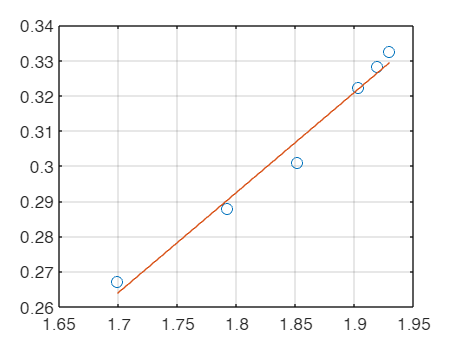

a =     0.2852   -0.2209


r2 = 0.9794

alpha = 10^(a(2))
beta  = a(1)

% Check by plotting
f = alpha*W.^beta;
plot(W,A,'b',W,f,'g')

% Power law equation

nlm = fitnlm(W,A,@(b,W)b(1)*W.^b(2), [1 1])

alpha = 0.6013

## Problem 45

% eigenvalues and vectors

beta = 0.2852

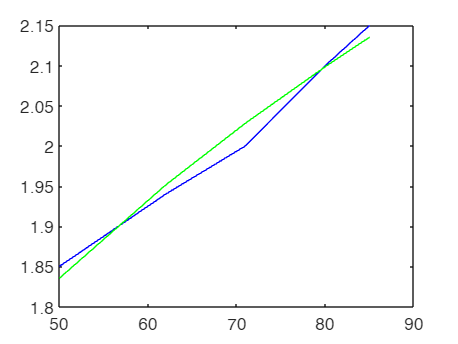

help eig
A = [-4 6; 66 -313];
[V,D] = eig(A)


% Check with characteristic eq
P = poly(A)
lamda = roots(P)

nlm = Nonlinear regression model:
    y ~ b1*W^b2

Estimated Coefficients:
          Estimate       SE       tStat       pValue  
          ________    ________    ______    __________

    b1    0.59284     0.054053    10.968    0.00039264
    b2    0.28857     0.021299    13.549    0.00017178


Number of observations: 6, Error degrees of freedom: 4
Root Mean Squared Error: 0.019
R-Squared: 0.98,  Adjusted R-Squared 0.974
F-statistic vs. zero model: 3.42e+04, p-value = 3.42e-09

## Problem 46

% Derivative
syms x
f = 3*exp(-0.9*x);
df = diff(f)

 eig    Eigenvalues and eigenvectors.
    E = eig(A) produces a column vector E containing the eigenvalues of 
    a square matrix A.
 
    [V,D] = eig(A) produces a diagonal matrix D of eigenvalues and 
    a full matrix V whose columns are the corresponding eigenvectors  
    so that A*V = V*D.
  
    [V,D,W] = eig(A) also produces a full matrix W whose columns are the
    corresponding left eigenvectors so that W'*A = D*W'.
 
    [...] = eig(A,"nobalance") performs the computation with balancing
    disabled, which sometimes gives more accurate results for certain
    problems with unusual scaling. If A is symmetric, eig(A,"nobalance")
    is ignored since A is already balanced.
 
    [...] = eig(A,"balance") is the same as eig(A).
 
    E = eig(A,B) produces a column vector E containing the generalized 
    eigenvalues of square ma

dfunc = matlabFunction(df);
dfunc_2 = dfunc(2)

V =     0.9781   -0.0193
    0.2081    0.9998


D =    -2.7237         0
         0 -314.2763



% Integral
f = @(x) (x-5./x).^4;

P =     1.0000  317.0000  856.0000


F = integral(f,1,3)

lamda =  -314.2763
   -2.7237



% check
hold off;
fplot(f,[1 3])

## Extra Credit

tspan = [0 2];
y0 = 1; h = 0.001;

$$df = -\frac{27\,{\mathrm{e}}^{-\frac{9\,x}{10}}}{10}$$

[t,y] = rk4(@dydtsys,tspan,y0,h);
plot(t,y)

dfunc_2 = -0.4463


% integrate
trapuneq(t,y)


F = 42.3506

% Notes
%   - you could also find a nonlinear model for y
%   - you could differentiate y at any point on [0 2]

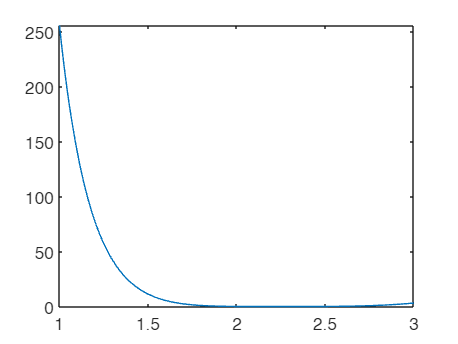

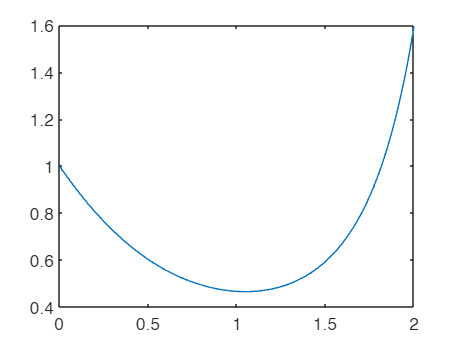

ans = 1.3653

 interp1 1-D interpolation (table lookup)
 
    Vq = interp1(X,V,Xq) interpolates to find Vq, the values of the
    underlying function V=F(X) at the query points Xq. 
 
    X must be a vector. The length of X is equal to N.
    If V is a vector, V must have length N, and Vq is the same size as Xq.
    If V is an array of size [N,D1,D2,...,Dk], then the interpolation is
    performed for each D1-by-D2-by-...-Dk value in V(i,:,:,...,:). If Xq
    is a vector of length M, then Vq has size [M,D1,D2,...,Dk]. If Xq is 
    an array of size [M1,M2,...,Mj], then Vq is of size
    [M1,M2,...,Mj,D1,D2,...,Dk].
 
    Vq = interp1(V,Xq) assumes X = 1:N, where N is LENGTH(V)
    for vector V or SIZE(V,1) for array V.
 
    Interpolation is the same operation as "table lookup".  Described in
    "table lookup" terms, the "table" is [X,V] and interp1 "looks-up"
    the elements of Xq in X, and, based upon their location, returns
   

%   - you could find the minimum of y on the interval